# Exploring Series

## Introduction

In this activity we will explore series $\sum_{k=1}^{\infty } a_k$ geometrically and symbolically. 

First, we will use the commands [`cumsum`](https://au.mathworks.com/help/matlab/ref/cumsum.html) and [`stem`](https://au.mathworks.com/help/matlab/ref/stem.html) to plot partial sums of series and try to determine whether they converge or diverge. Then we will calculate the limit of particular series using the commands [`symsum`](https://au.mathworks.com/help/symbolic/symsum.html) and [`limit`](https://au.mathworks.com/help/symbolic/limit.html).

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

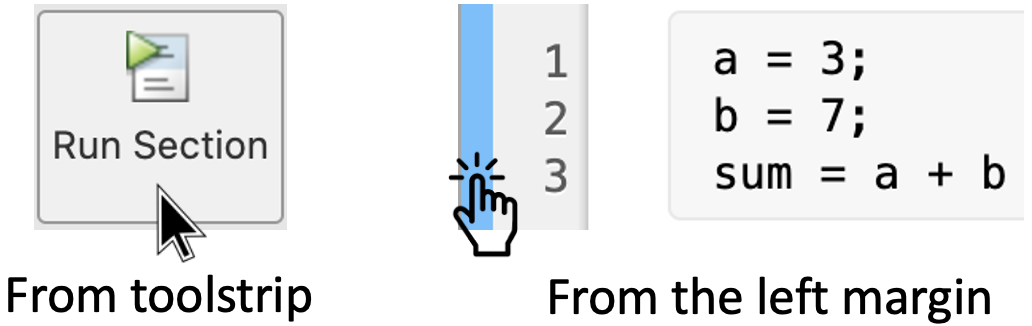

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Geometric exploration

### 1.1 Partial sums

It is possible to explore geometrically the series 


$$\sum_{k=1}^{\infty } a_k =a_1 +a_2 +\cdots$$


by considering the associated partial sums

${S_1 =\;a}_1$, $S_2 =a_1 +a_2$, $S_3 =a_1 +a_2 +a_3$

and, in general,


$$S_n =a_1 +a_2 +\cdots +a_n =\sum_{k=1}^n a_k \ldotp$$


These partial sums form a new sequence $\left\lbrace S_n \right\rbrace$, which may or may not have a limit. If


$$\lim_{n\to \infty } S_n =S$$


exits (as a finite number), then, we call this value $S$ the sum of the infinite series $\sum_{k=1}^{\infty } a_k$.

### 1.2 Plotting partial sums of series

Now consider the following series


$$\sum_{k=1}^{\infty } \frac{1}{k\left(k+1\right)}$$


To plot this first, let's create a variable:

n_last = 74;

This variable is an integer defined between 1 and 150.

We need to use the operator[ : ](https://au.mathworks.com/help/matlab/ref/colon.html)to define the domain of the sequence of partial sums. In this case we can store this information as a variable:

k = 1:n_last;

Now we just need to use the command [`cumsum`](https://au.mathworks.com/help/matlab/ref/cumsum.html) to define the partial sums and plot it witht the command [`stem`](https://au.mathworks.com/help/matlab/ref/stem.html). That is:

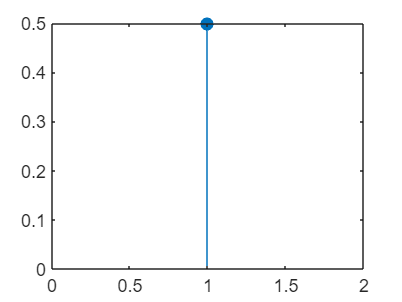

a(k) = cumsum( 1./(k.*(k+1)) );  % Define sequence of partial sums
stem(k, a(k), 'filled');         % Plot terms

**Remark:** Here we are using row vectors (also known as *arrays*) which means that the operations *multiplication*, *division* and *exponentiation* must have the *period *"`.`" before each operator: `*, /, ^`. Learn more about it here: [Arithmetic operations](https://au.mathworks.com/help/matlab/arithmetic-operators.html).

Run this section to see the plot. You can change the number of point in the plot by dragging the slider n_last.

## 2. Symbolic exploration

As you have noticed, in the previous section, the plot of the partial sums for the series


$$\sum_{k=1}^{\infty } \frac{1}{k\left(k+1\right)}$$


suggests that it has a limit. We can verify this symbolically using the commands [`symsum`](https://au.mathworks.com/help/symbolic/symsum.html) and [`limit`](https://au.mathworks.com/help/symbolic/limits.html).

First, we need to define two symbolic variables:

syms k n

Second, we define the partial sum as a symbolic expression:

Sn = symsum(1/(k*(k+1)), k, 1, n);

Finally, we calculate the limit:

limit(Sn, n, inf)

$$ans = 1$$

## 3. Hands on practice!

Let's practice what we just learned.

### Activity 1:

Use the commands [`cumsum`](https://au.mathworks.com/help/matlab/ref/cumsum.html) and [`stem`](https://au.mathworks.com/help/matlab/ref/stem.html) to plot 300 terms of the partial sums of the following series:

- 
$$\sum_{k=2}^{\infty } \frac{2}{k^2 -1}$$


- 
$$\sum_{k=4}^{\infty } \left(\frac{1}{\sqrt{k}}-\frac{1}{\sqrt{k+1}}\right)$$


- 
$$\sum_{k=1}^{\infty } \frac{{\left(-3\right)}^{k-1} }{4^k }$$


- 
$$\displaystyle \sum_{k=1}^{\infty}\frac{(-3)^{k-1}}{\sqrt{k}}$$


Analyse the plots in each case. What do you notice? Can you determine whether the series converges or diverges based on the information provided by its plot?

Write your code here:

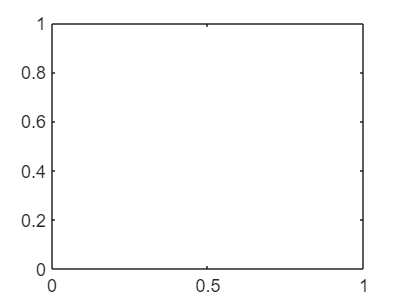

n_last = 300;
k = 1:n_last;


A = cumsum(2./(k.^2 -1));
stem(k, A, 'filled');

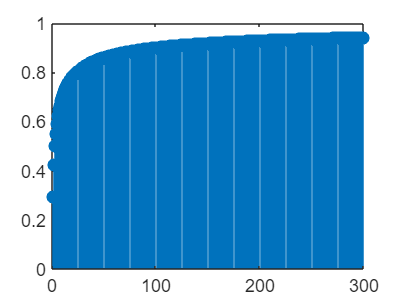



B = cumsum(1./k.^(1/2) - 1./(k+1).^(1/2));
stem(k, B, 'filled');

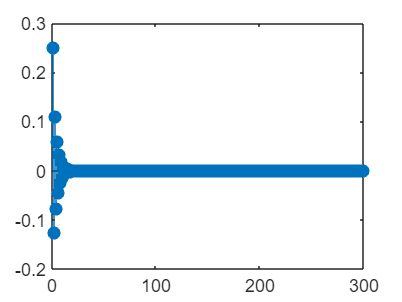


C = cumsum((-3).^(k-1))./(4.^k);
stem(k, C, 'filled');

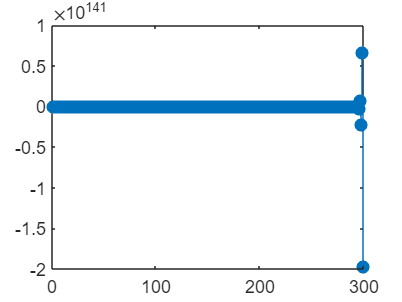


D = cumsum(((-3).^(k-1))./sqrt(k));
stem(k, D, 'filled');

### Activity 2:

Use the commands [`symsum`](https://au.mathworks.com/help/symbolic/symsum.html) and [`limit`](https://au.mathworks.com/help/symbolic/limits.html), as we did in section 2, to calculate the sum of the series from Activity 1.

Write your code here:

syms k


A = cumsum(2./(k.^2 -1))

$$A = \frac{2}{k^{2}-1}$$

limit(A, k, inf)

$$ans = 0$$


B = cumsum(1./k.^(1/2) - 1./(k+1)^(1/2))

$$B = \frac{1}{\sqrt{k}}-\frac{1}{\sqrt{k+1}}$$

limit(B, k, inf)

$$ans = 0$$


C = cumsum(((-3).^(k-1))/4.^k)

$$C = \frac{{\left(-3\right)}^{k-1}}{4^{k}}$$

limit(C,k,inf)

$$ans = 0$$


D = cumsum(((-3).^(k-1))/sqrt(k))

$$D = \frac{{\left(-3\right)}^{k-1}}{\sqrt{k}}$$

limit(D,k,inf)

$$ans = \mathrm{NaN}$$

### Activity 3:

In your notebook, determine whether the series from Activity 1 converge or diverge. You can use different tests to do so. Where possible, find the sum of the convergent series and compare your results with those provided by MATLAB.